# *Filtering of mp3 songs*

*1.1) Reading .mp3 file, writing it to .wav file and reading that .wav file*

*Fs - Sampling Frequency*

[xn, Fs] = audioread('Input_Signal.mp3');
audiowrite('Input_Signal.wav',xn(:,1),Fs);
[xn, Fs] = audioread('Input_Signal.wav');

*1.2) Fs = Sampling Frequency*

Fs

Fs = 44100

*This is the standard for most consumer audio, used for formats like CDs. Humans can hear frequencies between 20 Hz and 20 kHz. Most people lose their ability to hear upper frequencies over the course of their lives and can only hear frequencies up to 15 kHz–18 kHz. However, this “20-to-20” rule is still accepted as the standard range for everything we could hear. In addition, signals must be low-pass filtered before sampling to avoid aliasing. While an ideal low-pass filter would perfectly pass frequencies below 20 kHz (without attenuating them) and perfectly cut off frequencies above 20 kHz, such an ideal filter is theoretically and practically impossible to implement as it is noncausal, so in practice a transition band is necessary, where frequencies are partly attenuated. The wider this transition band is, the easier and more economical it is to make an anti-aliasing filter. The 44.1 kHz sampling frequency allows for a 2.05 kHz transition band.*

*1.3) DownSampling by 2 and 3 and seperately listening to them.*

xn2 = audioplayer(downsample(xn,2),Fs);
play(xn2)
xn3 = audioplayer(downsample(xn,3),Fs);
play(xn3)

*Downsampling is the process of reducing the sampling rate of a signal. It is done by considering the first sample and then every *`n`*th sample after the first.*

*Observations:*

- *By Downsampling the Data, No.of Samples got reduced. So the runtime of the file got reduced by Downsampling Factor. It can also be observed that as an effect of jump between samples, the files plays faster by Downsampling Factor.*

- *Downsampling file by factor of 3 makes the audio play more faster and shorter in time, than Downsampling file by factor of 2*

*1.4) Frequency Response*

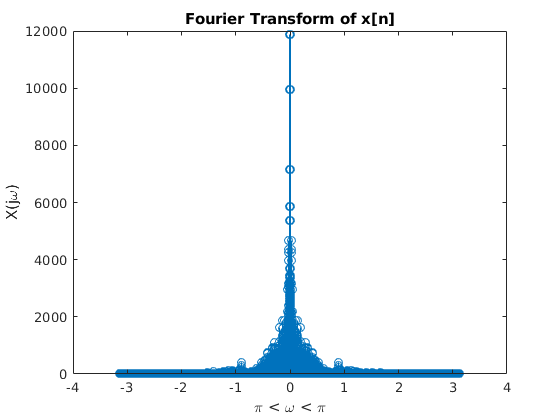

Xw = fftshift(fft(xn));
N = size(xn);
Ns = N(1);
w = 2*pi*(1*(-Ns/2:(Ns/2)-1)/Ns)';
stem(w,abs(Xw(:,1)))
title('Fourier Transform of x[n]')
xlabel('\pi < \omega < \pi')
ylabel('X(j\omega)')

*1.5) Low Pass Filter with Bandwidth Wo*

frac = 1/3;
Wo = frac*Fs;
t = ([-Ns:Ns-1]/Fs)';
s = size(t);
L = Ns

L = 543744

Length of Impulse Response is considered equal to that of Input Signal inorder to increase precision of Low Pass Filter.

n = ([-L/2:L/2 - 1]/Fs)';

ht = sinc(Wo*t);
hn = sinc(Wo*n)*frac;

Time Domain Response of h(t)

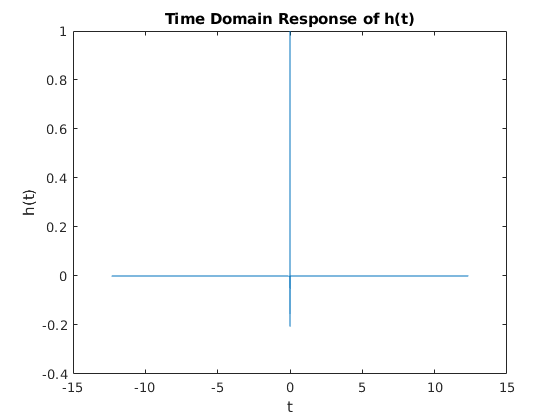

plot(t,ht);
title('Time Domain Response of h(t)')
xlabel('t')
ylabel('h(t)')

Time Domain Response of h[n]

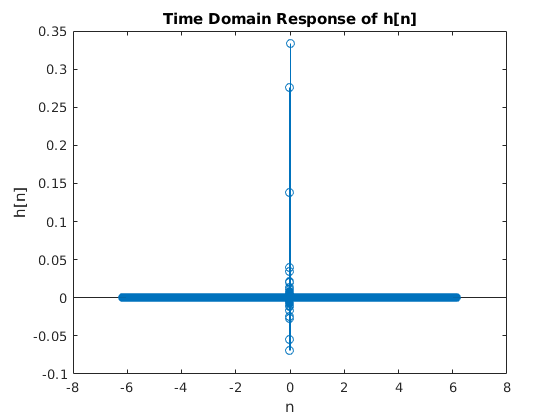

stem(n,hn);
title('Time Domain Response of h[n]')
xlabel('n')
ylabel('h[n]')

Fourier Transform of h[n]

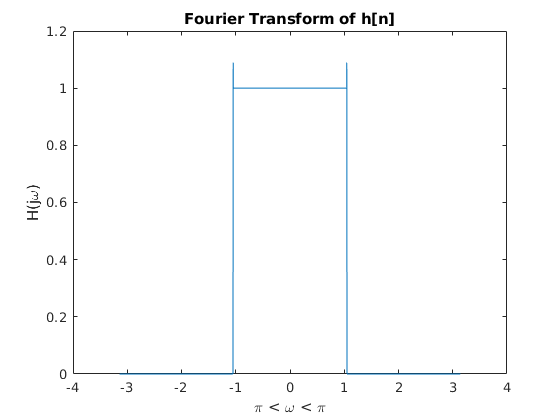

w = 2*pi*(1*(-Ns/2:(Ns/2)-1)/Ns)';
Hw = fftshift(fft(hn));
plot(w,abs(Hw))
title('Fourier Transform of h[n]')
xlabel('\pi < \omega < \pi')
ylabel('H(j\omega)')

Power of h[n]

Power_hn = mean(hn.*hn)

Power_hn = 6.1303e-07

*1.6) Passing Signal to Low Pass Filter*

yn = conv(xn,hn,'same');

*Playing Audio*

y = audioplayer(yn,Fs);
play(y)

High Frequency Components are Signal are attenuated.

*Plotting Frequency Response*

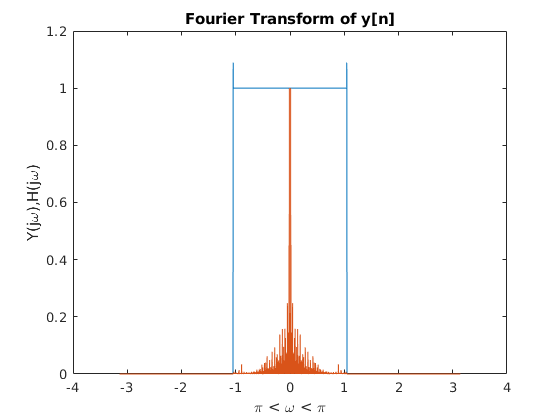

w = 2*pi*(1*(-Ns/2:(Ns/2)-1)/Ns)';
Yw = fftshift(fft(yn));
Hw = fftshift(fft(hn));

% Plotting Absolute Data
plot(w,abs(Hw))
hold on
% Plotting by Normalising Absolute Data
plot(w,abs(Yw)/max(abs(Yw)))
title('Fourier Transform of y[n]')
xlabel('\pi < \omega < \pi')
ylabel('Y(j\omega),H(j\omega)')
hold off

*Power Calculations*

Power_yn = mean(yn.*yn)

Power_yn = 0.0132

Power_xn = mean(xn.*xn)

Power_xn = 0.0133

*Power of y[n] is equal to Power of x[n] when it is passed through Low Pass Filter having Bandwidth equal to Fs.*

*Inother cases Power of x[n] = Power of y[n] for the frequency components present in y[n].*

*1.7) Creating and Passing Signal through a Band Pass Filter*

sn = exp(1i*(2*pi)*Wo*n/2);
bn = hn .* sn;

*Passing Signal Through a Band-Pass Filter*

ybn = conv(xn,bn,'same');

*Playing Audio*

yb = audioplayer(abs(ybn),Fs);
play(yb)

Increase in Disturbance or Audio Signal is Disrupted as when Signal is passed through a Band-Pass Filter Majority of components(in this case) are getting attenuated.

*Filter Visualisation*

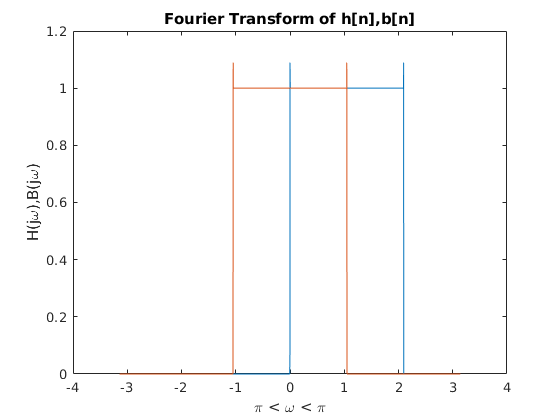

w = 2*pi*(1*(-Ns/2:(Ns/2)-1)/Ns)';
Bw = fftshift(fft(bn));
plot(w,abs(Bw))
hold on
plot(w,abs(Hw))
title('Fourier Transform of h[n],b[n]')
xlabel('\pi < \omega < \pi')
ylabel('H(j\omega),B(j\omega)')
hold off

*Plotting Frequency Response*

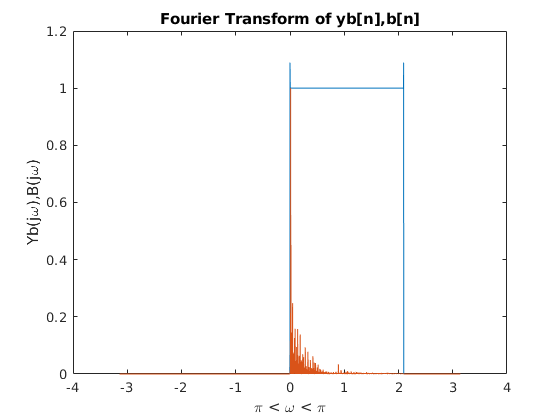

w = 2*pi*(1*(-Ns/2:(Ns/2)-1)/Ns)';
YBw = fftshift(fft(ybn));
Bw = fftshift(fft(bn));

% Plotting Absolute Value Data
plot(w,abs(Bw))
hold on
% Plotting by Normalising Absolute Data
plot(w,abs(YBw)/max(abs(YBw)))
title('Fourier Transform of yb[n],b[n]')
xlabel('\pi < \omega < \pi')
ylabel('Yb(j\omega),B(j\omega)')
hold off

*Power Calculations*

Power_ybn = mean(real(ybn).*real(ybn))

Power_ybn = 0.0033

Power_xn = mean(xn.*xn)

Power_xn = 0.0133